## Differential equations in Matlab (PSYC 9015 Topic 3B). 

This liveScript accompanies class materials for Topic 3B. These exercises use Matlab's Symbolic Toolbox. Please see [this resource](https://www.mathworks.com/help/symbolic/computational-mathematics-in-symbolic-math-toolbox.html) for an excellent introduction to this toolbox.

## Visualize HKB logic

syms f(x)
f(x)= -sin(2*x);
g(x) = -sin(x)

$$g(x) = -\sin\left(x\right)$$


figure
fplot(f(x))
hold

Current plot held


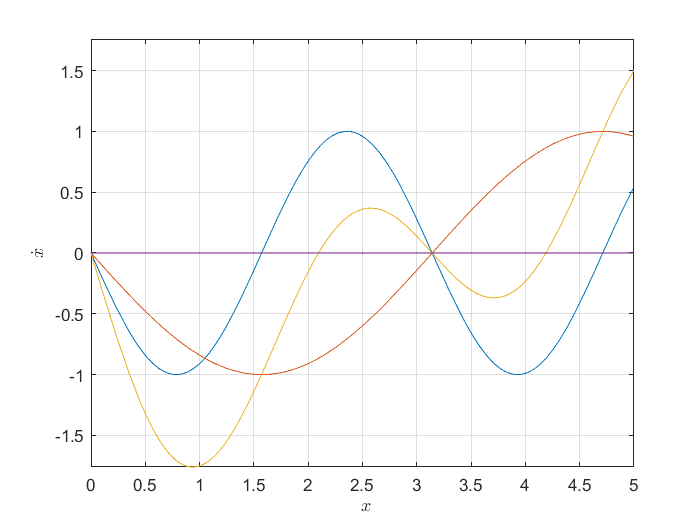

$$ans = \left(\begin{array}{c} 0\\ -\frac{2\,\pi }{3}\\ \frac{2\,\pi }{3} \end{array}\right)$$

fplot(g(x))
fplot(g(x)+f(x))
fplot(0) % add reference line for x dot = 0
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-.5 5])

## Plot the HKB equation for different values of b/a control parameter 

This way of ploting of the same equation with different paramter values is due to Nicole Carver - she found this nice way in her HW3 in this class.

syms f(x) 
b = [1,1,1,1]

b =      1     1     1     1


a = [1,2,3,4]

a =      1     2     3     4


f(x) = -a*sin(x)-2*b*sin(2*x);

figure
fplot(f(x))
hold

Current plot held


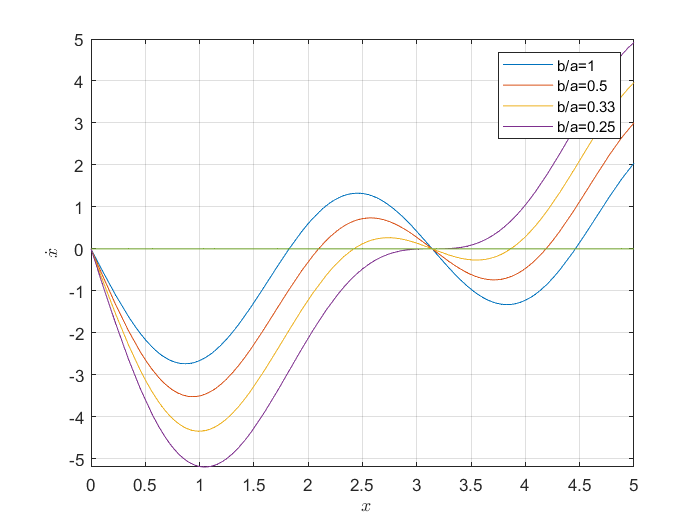

fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-0.5 5])
legend('b/a=1','b/a=0.5','b/a=0.33','b/a=0.25')

## HKB detuning parameter

This way of ploting of the same equation with different paramter values is due to Nicole Carver - she found this nice way in her HW3 in this class.

syms f(x) 
b = 1

b = 1

a = 1

a = 1

d_omega = [0,0.25,0.5]

d_omega =          0    0.2500    0.5000


f(x) = d_omega-a*sin(x)-2*b*sin(2*x);

figure
fplot(f(x))
hold

Current plot held


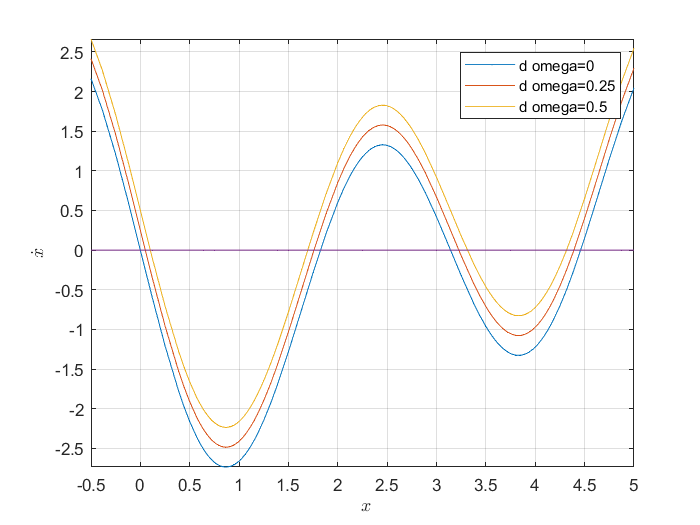

fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-0.5 5])
legend('d omega=0','d omega=0.25','d omega=0.5')

## Potential functions

syms f(x) v(x)
a = 1;
b = 1;
f(x) = -a*sin(x)-2*b*sin(2*x);


$$ans = -2\,\sin\left(2\,x\right)-\sin\left(x\right)$$

% Potential function V(x):
v(x) = int(-f(x), x)

$$v(x) = 6\,{\cos\left(\frac{x}{2}\right)}^{2}-8\,{\cos\left(\frac{x}{2}\right)}^{4}$$


figure
fplot(v(x))
hold

Current plot held


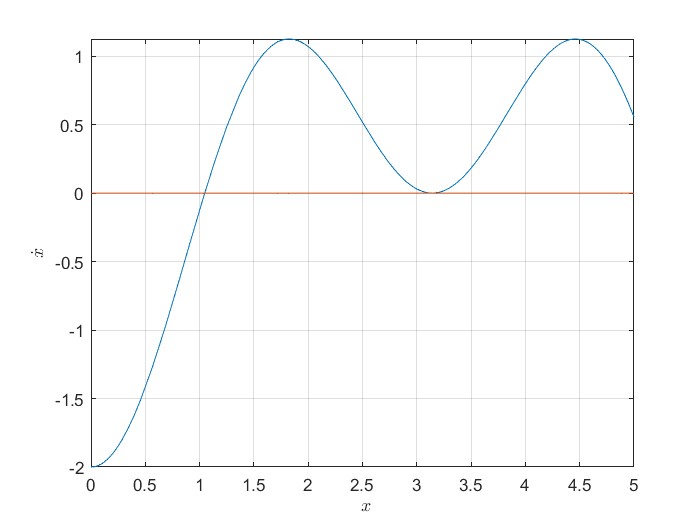

fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([0 5])

**Exercise ****1****: **Convert the following f(x) functions into V(x) functions using Matlab and plot the V(x) and f(x) functions together.

% Equation 1
syms f(x) V(x) r

f(x) = -r*x

$$f(x) = -r\,x$$

V(x) = int(-f(x))

$$V(x) = \frac{r\,x^{2}}{2}$$


% subsititue a specific r value
r_in = 0.1;
V(x) = subs(V(x),r,r_in)

$$V(x) = \frac{x^{2}}{20}$$

f(x) = subs(f(x),r,r_in)

$$f(x) = -\frac{x}{10}$$


figure
fplot(V(x))
hold

Current plot held


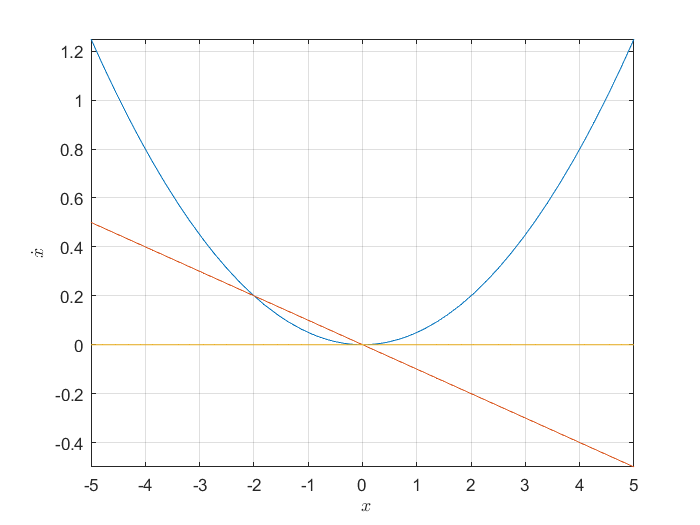

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')

% Equation 2
syms f(x) V(x) r

f(x) = r*(x-x^3)

$$f(x) = r\,\left(x-x^{3}\right)$$

V(x) = int(-f(x))

$$V(x) = \frac{r\,x^{2}\,\left(x^{2}-2\right)}{4}$$


% subsititue a specific r value
r_in = 0.7;
V(x) = subs(V(x),r,r_in)

$$V(x) = \frac{7\,x^{2}\,\left(x^{2}-2\right)}{40}$$

f(x) = subs(f(x),r,r_in)

$$f(x) = \frac{7\,x}{10}-\frac{7\,x^{3}}{10}$$

figure
fplot(V(x))
hold

Current plot held


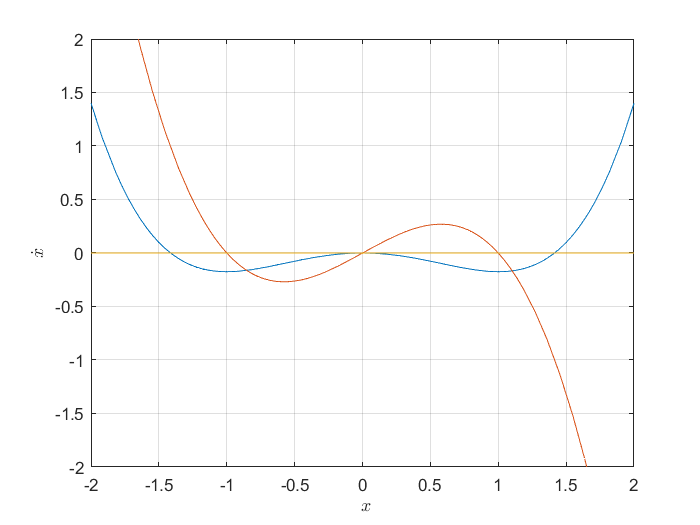

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-2 2])
ylim([-2 2])

% Equation 3
syms f(x) V(x) r

f(x) =-r+x-x^3

$$f(x) = -x^{3}+x-r$$

V(x) = int(-f(x))

$$V(x) = \frac{x\,\left(x^{3}-2\,x+4\,r\right)}{4}$$


% subsititue a specific r value
r_in = 0.7;
V(x) = subs(V(x),r,r_in)

$$V(x) = \frac{x\,\left(x^{3}-2\,x+4\right)}{4}$$

f(x) = subs(f(x),r,r_in)

$$f(x) = -x^{3}+x-1$$


figure
fplot(V(x))
hold

Current plot held


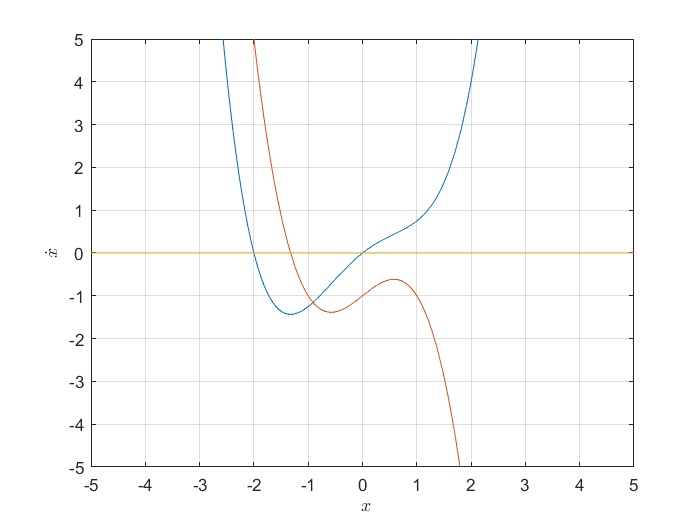

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-5 5])
ylim([-5 5])

% Equation 4
syms f(x) V(x) a b

f(x) =-a*sin(x)-2*b*sin(2*x)

$$f(x) = -2\,b\,\sin\left(2\,x\right)-a\,\sin\left(x\right)$$

V(x) = int(-f(x))

$$V(x) = 8\,b\,{\cos\left(\frac{x}{2}\right)}^{2}-2\,a\,{\cos\left(\frac{x}{2}\right)}^{2}-8\,b\,{\cos\left(\frac{x}{2}\right)}^{4}$$


% subsititue a specific r value
a_in = 1;
b_in = 1;
V(x) = subs(V(x),{a,b},{a_in,b_in})

$$V(x) = 6\,{\cos\left(\frac{x}{2}\right)}^{2}-8\,{\cos\left(\frac{x}{2}\right)}^{4}$$

f(x) = subs(f(x),{a,b},{a_in,b_in})

$$f(x) = -2\,\sin\left(2\,x\right)-\sin\left(x\right)$$


figure
fplot(V(x))
hold

Current plot held


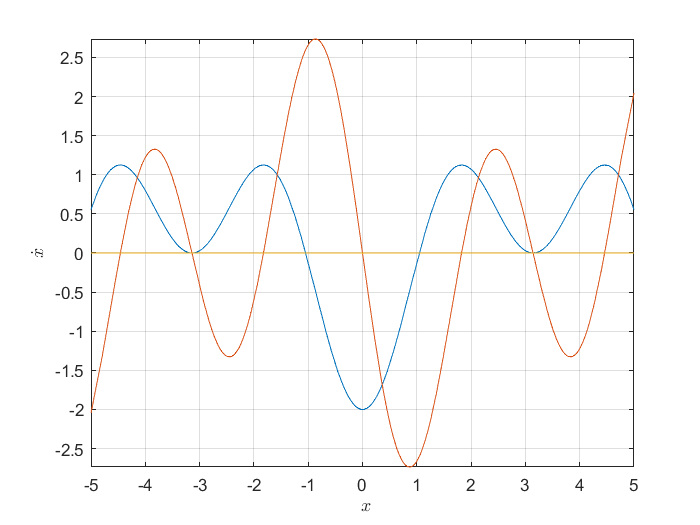

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')

**Exercise 2****: **Convert the following V(x) functions into ODEs using Matlab: 

% Equation 1
syms f(x) V(x) r
V(x) = (r*x^2)/2

$$V(x) = \frac{r\,x^{2}}{2}$$

f(x) = diff(-V(x))

$$f(x) = -r\,x$$


V(x) = ((r*x^2)*(x^2-2))/4

$$V(x) = \frac{r\,x^{2}\,\left(x^{2}-2\right)}{4}$$

f(x) = diff(-V(x))

$$f(x) = -\frac{r\,x^{3}}{2}-\frac{r\,x\,\left(x^{2}-2\right)}{2}$$


% note that we can tidy up this derivative expression using the simplify
% function
help simplify

--- help for sym/simplify ---

 simplify Symbolic simplification.
    simplify(S) simplifies each element of the symbolic matrix S.
    
    simplify(S,N) or, equivalently, simplify(S,'Steps',N),
    searches for a simplification in N steps. The default value of N is 1.
    
    simplify(S,'Seconds',T) aborts the search for a simpler version
    at the next end of a simplification step after T seconds. The results
    will depend on the speed and system load of your computer and may
    not be reproducible.
    
    simplify(S,'IgnoreAnalyticConstraints',VAL) controls the level of 
    mathematical rigor to use on the analytical constraints while simplifying 
    (branch cuts, division by zero, etc). The options for VAL are TRUE or 
    FALSE. Specify TRUE to relax the level of mathematical rigor
    in the rewriting process. The default is FALSE.
    
    simp

simplify(f(x))

$$ans = -r\,x\,\left(x^{2}-1\right)$$

Function 3

V(x) = (x*(x^3-2*x+4*r))/4

$$V(x) = \frac{x\,\left(x^{3}-2\,x+4\,r\right)}{4}$$

f(x) = diff(-V(x))

$$f(x) = \frac{x}{2}-r-\frac{x\,\left(3\,x^{2}-2\right)}{4}-\frac{x^{3}}{4}$$

simplify(f(x))

$$ans = -x^{3}+x-r$$

## Bifurcation theory examples

### Saddle node bifurcation

syms f(x) V(x) r

f(x) = r+x^2

$$f(x) = x^{2}+r$$

V(x) = int(-f(x))

$$V(x) = -\frac{x^{3}}{3}-r\,x$$


% subsititue a specific r value
r_in = -0.3;
V(x) = subs(V(x),r,r_in)

$$V(x) = \frac{3\,x}{10}-\frac{x^{3}}{3}$$

f(x) = subs(f(x),r,r_in)

$$f(x) = x^{2}-\frac{3}{10}$$


figure
fplot(V(x))
hold

Current plot held


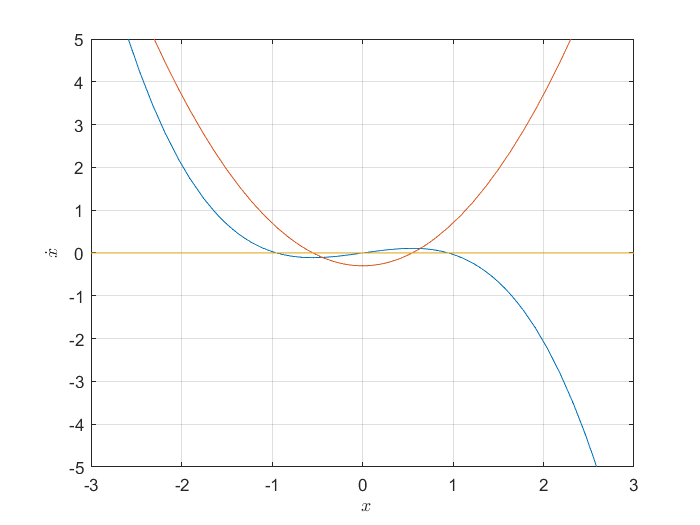

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-3 3])
ylim([-5 5])

### Transcritical bifurcation

syms f(x) V(x) r

f(x) = r*x-x^2

$$f(x) = r\,x-x^{2}$$

V(x) = int(-f(x))

$$V(x) = -\frac{x^{2}\,\left(3\,r-2\,x\right)}{6}$$


% subsititue a specific r value
r_in = -0.6;
V(x) = subs(V(x),r,r_in)

$$V(x) = \frac{x^{2}\,\left(2\,x+\frac{9}{5}\right)}{6}$$

f(x) = subs(f(x),r,r_in)

$$f(x) = -x^{2}-\frac{3\,x}{5}$$


figure
fplot(V(x))
hold

Current plot held


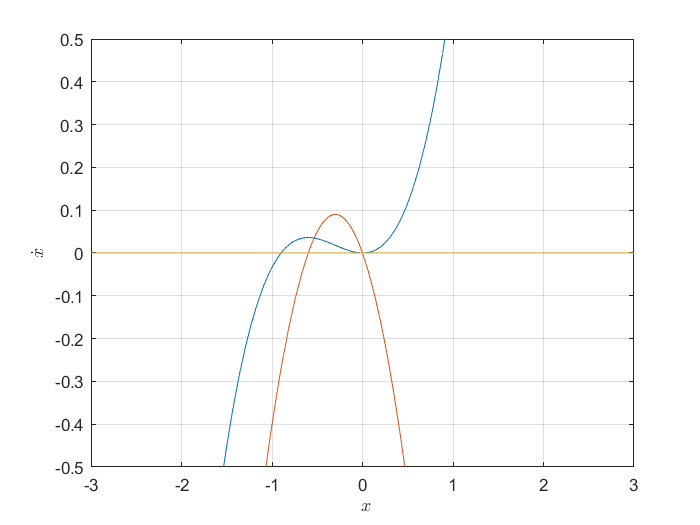

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-3 3])
ylim([-.5 .5])

### 'Supercritical' Pitchfork Bifurcation

syms f(x) V(x) r

f(x) = r*x-x^3

$$f(x) = r\,x-x^{3}$$

V(x) = int(-f(x))

$$V(x) = -\frac{x^{2}\,\left(2\,r-x^{2}\right)}{4}$$


% subsititue a specific r value
r_in = 0.7;
V(x) = subs(V(x),r,r_in)

$$V(x) = \frac{x^{2}\,\left(x^{2}-\frac{7}{5}\right)}{4}$$

f(x) = subs(f(x),r,r_in)

$$f(x) = \frac{7\,x}{10}-x^{3}$$


figure
fplot(V(x))
hold

Current plot held


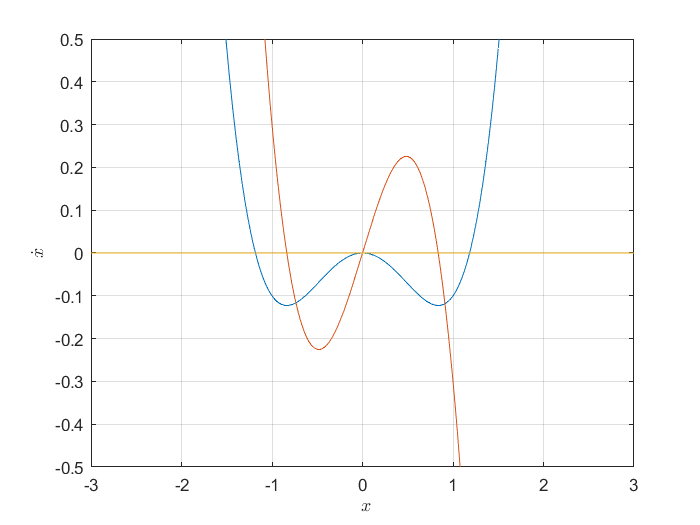

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-3 3])
ylim([-.5 .5])

### 'Subcritical' Pitchfork Bifurcation

syms f(x) V(x) r

f(x) = r*x+x^3

$$f(x) = x^{3}+r\,x$$

V(x) = int(-f(x))

$$V(x) = -\frac{x^{2}\,\left(x^{2}+2\,r\right)}{4}$$


% subsititue a specific r value
r_in = 0.7;
V(x) = subs(V(x),r,r_in)

$$V(x) = -\frac{x^{2}\,\left(x^{2}+\frac{7}{5}\right)}{4}$$

f(x) = subs(f(x),r,r_in)

$$f(x) = x^{3}+\frac{7\,x}{10}$$


figure
fplot(V(x))
hold

Current plot held


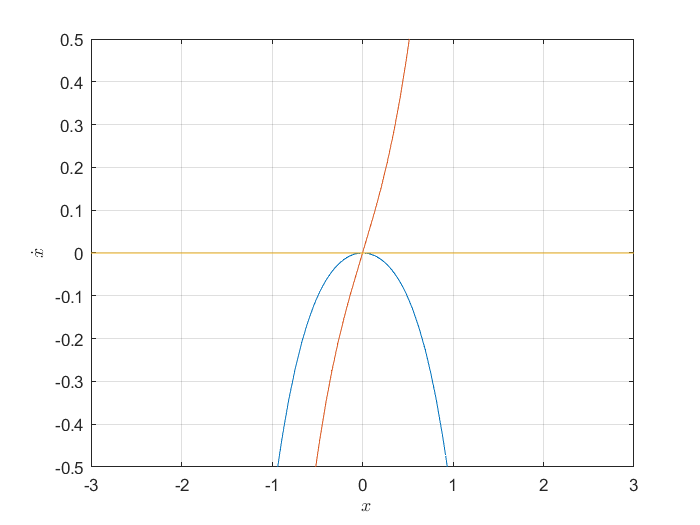

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-3 3])
ylim([-.5 .5])

### HKB: Example of pitchfork bifurcation

syms f(x) V(x) a b

f(x) =-a*sin(x)-2*b*sin(2*x)

$$f(x) = -2\,b\,\sin\left(2\,x\right)-a\,\sin\left(x\right)$$

V(x) = int(-f(x))

$$V(x) = 8\,b\,{\cos\left(\frac{x}{2}\right)}^{2}-2\,a\,{\cos\left(\frac{x}{2}\right)}^{2}-8\,b\,{\cos\left(\frac{x}{2}\right)}^{4}$$


% subsititue a specific r value
a_in = 0.9;
b_in = 1;
disp(['b/a =' num2str(b_in/a_in)])

b/a =1.1111



V(x) = subs(V(x),{a,b},{a_in,b_in});
f(x) = subs(f(x),{a,b},{a_in,b_in});

figure
fplot(V(x))
hold

Current plot held


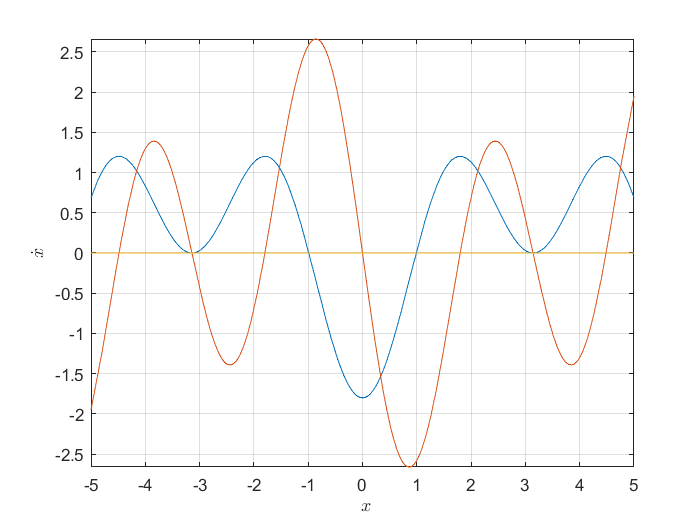

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')

###  Anoter example bifurcation

syms f(x) V(x) r

f(x) = r*x+x^3-x^5

$$f(x) = -x^{5}+x^{3}+r\,x$$

V(x) = int(-f(x))

$$V(x) = -\frac{x^{2}\,\left(-2\,x^{4}+3\,x^{2}+6\,r\right)}{12}$$


% subsititue a specific r value
r_in = -0.5;
V(x) = subs(V(x),r,r_in)

$$V(x) = \frac{x^{2}\,\left(2\,x^{4}-3\,x^{2}+3\right)}{12}$$

f(x) = subs(f(x),r,r_in)

$$f(x) = -x^{5}+x^{3}-\frac{x}{2}$$


figure
fplot(V(x))
hold

Current plot held


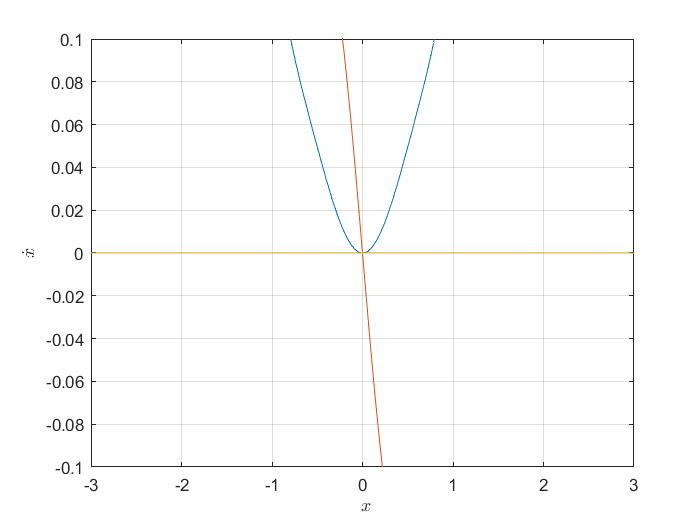

fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
xlim([-3 3])
ylim([-.1 .1])

### Cusp catastrohe

syms f(x) V(x) a b

f(x) =a+b*x-x^3

$$f(x) = -x^{3}+b\,x+a$$

V(x) = int(-f(x))

$$V(x) = -\frac{x\,\left(-x^{3}+2\,b\,x+4\,a\right)}{4}$$


% subsititue a specific r value
a_in = 0.5;
b_in = 0.8;
disp(['b/a =' num2str(b_in/a_in)])

b/a =1.6



V(x) = subs(V(x),{a,b},{a_in,b_in});
f(x) = subs(f(x),{a,b},{a_in,b_in})

$$f(x) = -x^{3}+\frac{4\,x}{5}+\frac{1}{2}$$


figure
fplot(V(x))
hold

Current plot held


fplot(f(x))
fplot(0)
grid on
xlabel('$\ x$','interpreter','latex')
ylabel('$\dot x$','interpreter','latex')
% xlim([-5 5])
% ylim([-.5 .5])